# **Plot Permeability Ratio Change Due to Line Load on 2D Elastic Half-Space**

#### Source: Amos et al., (2014) [https://www.nature.com/articles/nature13275#Sec6](https://www.nature.com/articles/nature13275#Sec6)

## User Inputs

clear; clf; close all;

% Line-Load "Glacier"
initialHeight = 1000; % [m]
finalHeight = 1000; %[m]
initialHalfWidth = 10000; % [m]
finalHalfWidth = 2000; % [m]

phi =40; % [degree] from positive horizontal
plot_with_lithostatic_stress = false;
grdRho =2.3; % [g cm^-3] density of the ground

iter = 2; % iterations, increase for higher resolution in video file

## Constants

rho = 917; % [kg m^-3] density of ice
g = 9.77; % [m s^-2] gravitational acceleration

phi = phi*pi/180;

h = linspace(initialHeight,finalHeight,iter); % [m] glacier height
a = linspace(initialHalfWidth,finalHalfWidth,iter); % [m] glacier half-width
No = rho*g*h.*a; % [N m^-1]
A = No./(2*pi*a); % [N m^-2]

step = 10; % m
x = 0:step:(max(a) + 1000); % m
step = 10;
z = 0:step:3000; % m

## Stress Feild Calculation

tic
[sigma_xx, sigma_xz, sigma_zz] = XZ_Stress(A, x, z, a);
sigma_normal = Normal_Stress(sigma_xx, sigma_xz, sigma_zz, phi);
if plot_with_lithostatic_stress == 1
    sigma_lith = Lithostatic_Stress(grdRho,x,z,h,g);
else
    sigma_lith = 0;
end
k = Permeability_Ratio_Calculator(sigma_normal + sigma_lith);
disp('Calculation finished'); toc

Calculation finished
Elapsed time is 0.123138 seconds.


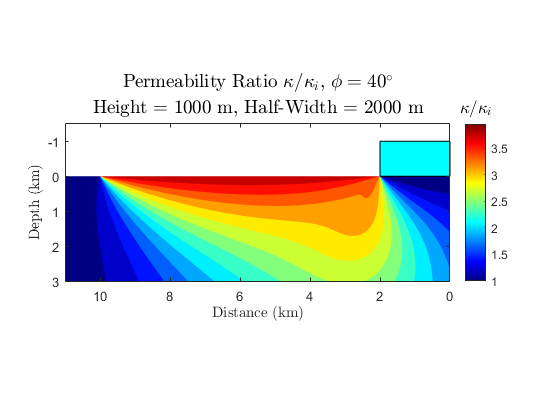

G = Plot_Permeability_Ratio(x, z, h, a, phi, k);

% Frames saved in F can be turned into .mp4 with Create_Video_File.m in the
% current directory